The experiment consisted of a circular trajectory and arm deployment. This was to validate the new laboratory software as well as to test the added sensors. First we load the data.

load('ExperimentData_Merged_2022_6_14_13_40.mat');

Now we plot the attitude from the IMU and PhaseSpace for the RED platform.

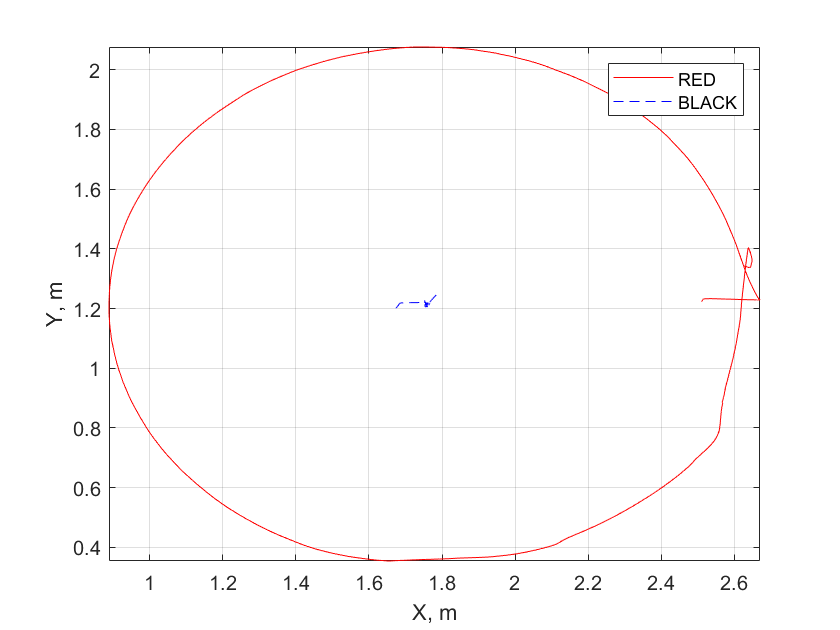

figure()
plot(dataClass.RED_Px_m(200:end), dataClass.RED_Py_m(200:end),'-r')
hold on
grid on
axis tight
plot(dataClass.BLACK_Px_m(200:end), dataClass.BLACK_Py_m(200:end),'--b')
xlabel('X, m')

ylabel('Y, m')
legend('RED','BLACK','location','northeast')

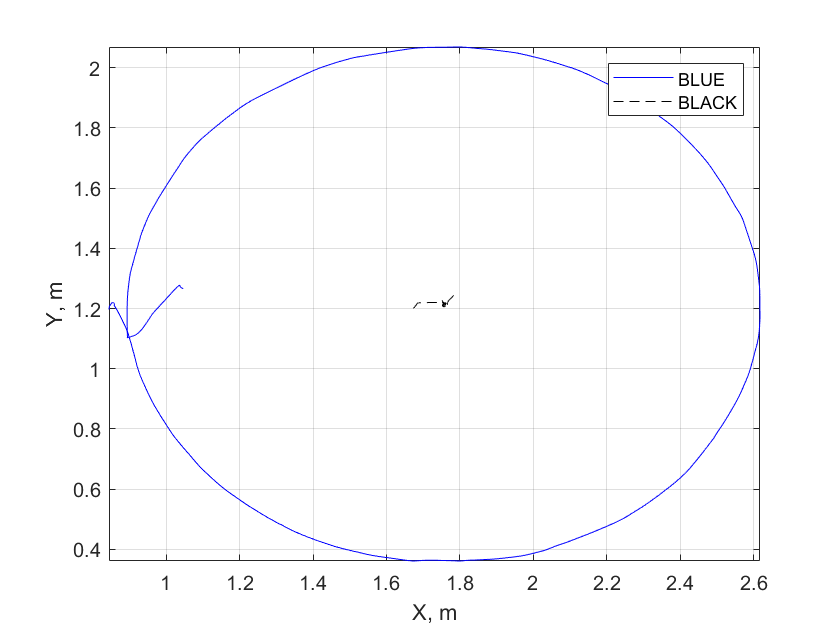

figure()
plot(dataClass.BLUE_Px_m(400:end), dataClass.BLUE_Py_m(400:end),'-b')
hold on
grid on
axis tight
plot(dataClass.BLACK_Px_m(200:end), dataClass.BLACK_Py_m(200:end),'--k')
xlabel('X, m')

ylabel('Y, m')
legend('BLUE','BLACK','location','northeast')

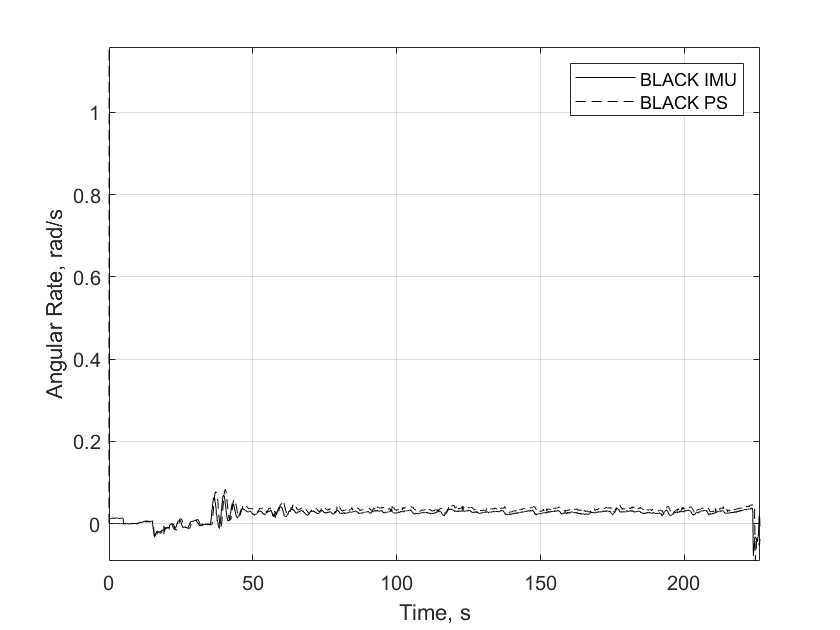

figure()
plot(dataClass.Time_s,dataClass.BLACK_GyroZ_Raw_radpers,'-k')
hold on
grid on
axis tight
plot(dataClass.Time_s, dataClass.BLACK_RzD_radpers,'--k')
xlabel('Time, s')

ylabel('Angular Rate, rad/s')
legend('BLACK IMU','BLACK PS','location','northeast')